# A3 | Plotting in MATLAB

Assignment type = **Individual**; Points = **12**

**Due at the start of class on 3/2.**

This assignment will have a single live script file (.mlx) which will incorporate solutions for four different problems. 

Other modifications:

- Only one header is needed and it should  include a list of the problems included and the names of variables associated.

- Make sure to include lots of comments in the code.

- Make sure naming conventions are unique so as not to overwrite variables.

- Save this file as A3_gulogin.mlx

% FUNCTION_NAME - Calculate the maximum efficiency of a pump
% Assignment: A3_Problem_1-4
%
% Inputs: P1 income, P2 volume, P3 xArray yArray, P4 force springDeflection
% Outputs: Poverty, volumePlot, subPlot, lineBestFit
%
% Author: Gabe DiMartino
% Date: 02/27/2023; Last revision: 27-February-2023
%------------- BEGIN CODE --------------
clear;
clc;

**Problem 1 | Pseudo-random number generation.**

Create a undeclared function to determine the number of households experiencing poverty in the United States.  Undeclared functions are standalone functions that do not have any  arguments that require passing inputs or returning outputs within the function definition.

The poverty threshold, poverty limit or poverty line is the minimum level of [income](https://en.wikipedia.org/wiki/Income) deemed adequate in a particular country. Within the United States the average income in 2019 was $47,060 and the standard deviation was $26,145 for 125.58 million households. However, a considerable number of those households do not meet the poverty threshold income of $25,750 (for a family of four). 

Using the information provided above, determine the number of households that make less than the poverty threshold. The output should read: In 2019, there were _____ <integer> households that were below the poverty line which is XX.X% of the population.

[povertyTotal,percentPoverty]=howManyPoverty();
fprintf('In 2019, there were %0.0f housholds that were below the poverty line which is %0.0f%% of the population.', povertyTotal, percentPoverty)

In 2019, there were 26066301 housholds that were below the poverty line which is 21% of the population.

**Problem 2** | **Plotting within MATLAB**

Download the excel file *volumeData.xlsx* on Blackboard.  Use the command **readmatrix()** to import the table into MATLAB. Use array indexing to separate the columns of this array into a distance and volume arrays. The first column is designated as the distance (x) in cm and the second column is volume in cm^3. Using the **plot** built-in function, create a figure that has the following:

- A dashed line

- Square point markers

- Green line color

Make sure to include proper APA formatting ( unique title (NOT x vs. y), axis labels w/ units, grid lines). 

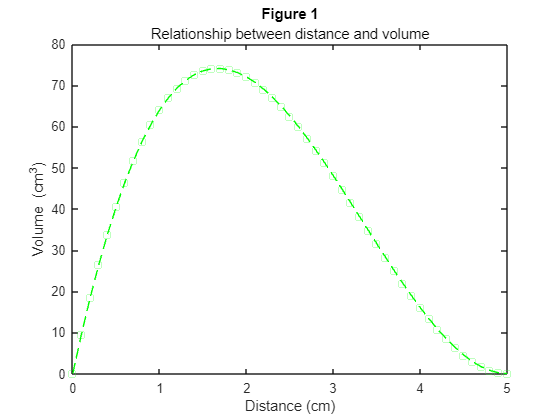

volumeData = readmatrix("volumeData.xlsx");
distance = volumeData(1:end,1);
volume = volumeData(1:end,2);

plot(distance,volume,'--gs')
title('Figure 1')
subtitle('Relationship between distance and volume')
xlabel('Distance (cm)')
ylabel('Volume (cm^3)')

**Problem 3 | Subplotting Configuration**

Create the equations below as xArray and yArray.

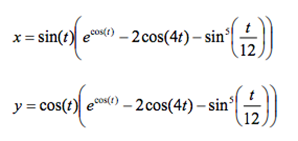

Designate an array t that goes from 0 to 12*pi in increments of 0.01*pi. Create commands for 3 different figures to be placed in a 3 x 3 subplot grid with designated specifiers embedded into the code. **Hint**: Make sure the correct value is on the x-axis. The upper left corner should plot xArray and t with a solid line in green.The second row on the right should plot yArray and t in blue. The bottom center position should plot xArray and yArray and should be a dotted line in magenta.

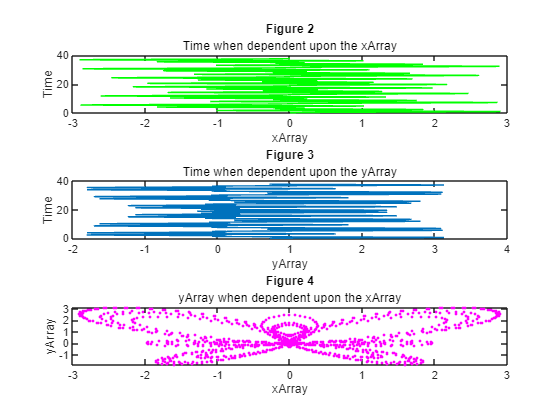

time = 0:(0.01*pi):(12*pi);

subplot(3,1,1);
x1 = time;
y1 = sin(time).*(exp(cos(time))-(2*cos(4.*time))-sin(time./12).^5);
plot(y1,x1,'g')
title('Figure 2')
subtitle('Time when dependent upon the xArray')
xlabel('xArray')
ylabel('Time')
subplot(3,1,2);
y2 = cos(time).*(exp(cos(time))-(2*cos(4.*time))-sin(time./12).^5);
plot(y2,x1)
title('Figure 3')
subtitle('Time when dependent upon the yArray')
xlabel('yArray')
ylabel('Time')

subplot(3,1,3);
plot(y1,y2,'.m')
title('Figure 4')
subtitle('yArray when dependent upon the xArray')
xlabel('xArray')
ylabel('yArray')

**Problem 4 | Mathematical model of Spring Deflection**

When trying to model a system, engineers use mathematics to help describe how data behaves. The data given below represents the force-deflection data points on a spring. 

forceArray = [5, 10, 15, 20, 25, 30, 35, 40];
springDeflection = [9, 18, 29, 35, 42, 48, 53, 58];
p = polyfit(forceArray,springDeflection,1);
lineBestFit = polyval(p,forceArray);

Find the equation that best fits the force-deflection data given using polyfit (hint: you will need to determine the order of best fit).  Create a plot of the data using “five pointed stars” as the data points from above along with the polyfit equation (solid line with no markers). Make sure that the plot is properly formatted (e.g. title, labels, legend).

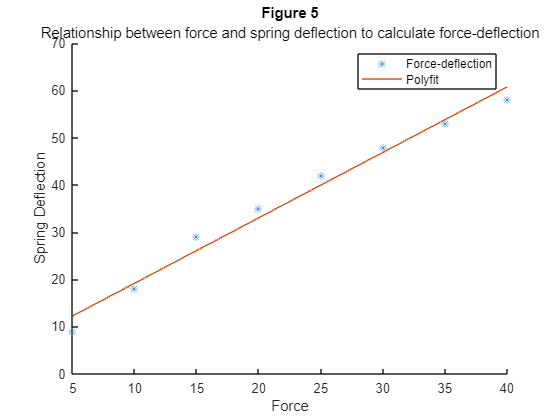

subplot(1,1,1);
scatter(forceArray,springDeflection,'*')
hold on
plot(forceArray,lineBestFit)
hold off
legend('Force-deflection','Polyfit')
title('Figure 5')
subtitle('Relationship between force and spring deflection to calculate force-deflection')
xlabel('Force')
ylabel('Spring Deflection')

function [povertyTotal,percentPoverty] = howManyPoverty()
averageIncome = 47060;
stDevIncome = 26145;
population = 125.58*1000000;
thresholdIncome = 25750;

randIncome = averageIncome+stDevIncome.*randn(1,population);
povertyTotal = length(randIncome(randIncome < thresholdIncome));
percentPoverty = (povertyTotal/length(randIncome))*100;

end